# Hardpoint Forces Calculator

Original author: Graeme Dockrill, VDX sub-team member 2022

Modified by: Liam Foster, mechanical lead 2022-2024

Description: 

This script reads suspension hardpoints and input forces from the "Brightside V2 Suspension Geometry Design" Google Sheet, plots the suspension system in 3D, and calculates the forces in each member. It assumes a left corner from the driver's perspective and therefore the right wheels are outboard and see the most load. This is the consistent with the worst case scenario as the motor wheel is on the right and therefore seeing the most load possible.

% Clear the console and all variables
clear
clc

% Choose turn direction
TurnDir = -1;
% Choose loading in gs (*9.81m/s^2)
BrakeLoadCase = 1;
CornerLoadCase = 1;
BumpLoadCase = 2;

## Initialization & Data Pulling

% ----------------Setup----------------------------------------------------

% Constants
grav = 9.81; % [m/s^2]
hardpointsize = 10;
linewidth = 1.5;
unitvect_scalefactor = 0.05;
unitvect_linewidth = 1.5;
forcevect_scalefactor = 2;
forcevect_linewidth = 1.5;
coordNames = ["O","MC","LCA_IR","LCA_IF","LCA_O","UCA_IR","UCA_IF","UCA_O",...
    "PR_O","PR_I","RP","RS","SC","TR_O","TR_I","WC","TP"];
reflectY = [1 0 0; 0 -1 0; 0 0 1];

% x,y,z for clearer equations
x = 1;
y = 2;
z = 3;

% Extracts balljoint coordinates from google sheets
ID = '1UxrHRz9iydKkYqhXAQWLDXY1FJoSzHCgv_TjBJgwtKQ';
sheet_name = 'Hardpoints';
url_name = sprintf('https://docs.google.com/spreadsheets/d/%s/gviz/tq?tqx=out:csv&sheet=%s',...
    ID, sheet_name);
data = webread(url_name);
X = data.X(4:39);
Y = data.Y(4:39);
Z = data.Z(4:39);

FLcoords = table(X(5:21),Y(5:21),Z(5:21));
FLcoords.Properties.RowNames = coordNames;
FLcoords.Properties.VariableNames = {'X' 'Y' 'Z'};
FRcoords = table(X(5:21),-Y(5:21),Z(5:21));
FRcoords.Properties.RowNames = coordNames;
FRcoords.Properties.VariableNames = {'X' 'Y' 'Z'};
RLcoords = table([X(5:6);X(22:end)],[Y(5:6);Y(22:end)],[Z(5:6);Z(22:end)]);
RLcoords.Properties.RowNames = coordNames;
RLcoords.Properties.VariableNames = {'X' 'Y' 'Z'};
RRcoords = table([X(5:6);X(22:end)],[-Y(5:6);-Y(22:end)],[Z(5:6);Z(22:end)]);
RRcoords.Properties.RowNames = coordNames;
RRcoords.Properties.VariableNames = {'X' 'Y' 'Z'};

% Modification for motor wheel spacer
RRcoords{"WC","Y"} = RRcoords{"WC","Y"} + (0.4*0.0254);
RRcoords{"TP","Y"} = RRcoords{"TP","Y"} + (0.4*0.0254);

% Initialize masses and parameters
masses = table(data{1:3,"X"},RowNames=data.Variable(1:3));
masses = renamevars(masses,"Var1","Mass");
masses{"m_Total","Mass"} = masses{"m_BS",:} + masses {"m_Driver",:};

COM = data{4,3:5};
track = data{5,'Y'};
wheelbase = data{6,'X'};
lotusOffset = data{7,'X'};

% Calculating weight transfer effects due to loading
RBias = (COM(x)-lotusOffset)/wheelbase;  % Static weight bias on rear wheels
BrakeLoadTransfer = COM(z)/wheelbase;                  % Fraction of load transferred to front wheels during braking
CornerLoadTransfer = COM(z)/track;                     % Fraction of load transferred to outside wheels during cornering

% Calculating static weights on each wheel
wS_F = masses{"m_Total",:}*(1-RBias)/2;                     % Static weight [kg] on each front wheel
wS_RL = (masses{"m_Total",:}*RBias-masses{"m_Motor",:})/2;  % Static weight [kg] on rear left wheel
wS_RR = wS_RL + masses{"m_Motor",:};                        % Static weight [kg] on rear right wheel (motor wheel)

% Calculating dynamic weights on each wheel accounting for weight transfer effects [kg]
wD_FL_TP = wS_F*(1+BrakeLoadCase*BrakeLoadTransfer)*(1+CornerLoadCase*CornerLoadTransfer*TurnDir);
wD_FR_TP = wS_F*(1+BrakeLoadCase*BrakeLoadTransfer)*(1-CornerLoadCase*CornerLoadTransfer*TurnDir);
wD_RL_TP = wS_RL*(1-BrakeLoadCase*BrakeLoadTransfer)*(1+CornerLoadCase*CornerLoadTransfer*TurnDir);
wD_RR_TP = wS_RR*(1-BrakeLoadCase*BrakeLoadTransfer)*(1-CornerLoadCase*CornerLoadTransfer*TurnDir);

% Calculating loads on each wheel according to the load cases [N]
f_FL_TP = wD_FL_TP*grav.*[BrakeLoadCase CornerLoadCase BumpLoadCase];
f_FR_TP = wD_FR_TP*grav.*[BrakeLoadCase CornerLoadCase BumpLoadCase];
f_RL_TP = wD_RL_TP*grav.*[BrakeLoadCase CornerLoadCase BumpLoadCase];
f_RR_TP = wD_RR_TP*grav.*[BrakeLoadCase CornerLoadCase BumpLoadCase];

% Construct SuspensionCorner classes for each wheel
Corner_FL = SuspensionCorner(FLcoords);
Corner_FR = SuspensionCorner(FRcoords);
Corner_RL = SuspensionCorner(RLcoords);
Corner_RR = SuspensionCorner(RRcoords);

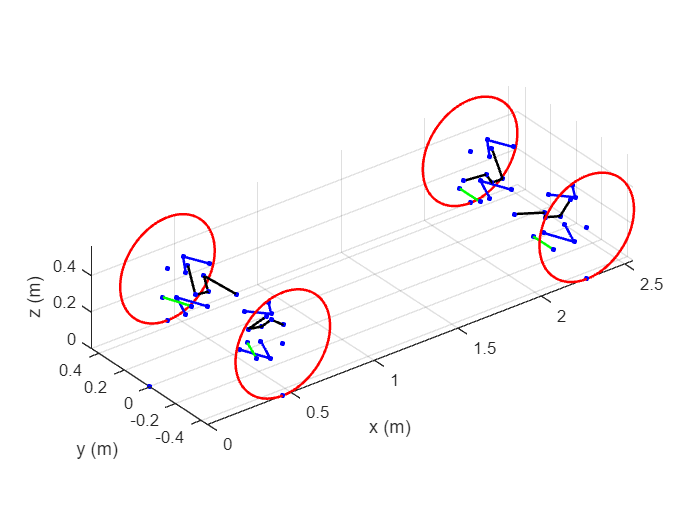

% Plot each suspension corner in the same figure
figFull = figure;
plotCorner(Corner_FL,figFull,hardpointsize,linewidth);
plotCorner(Corner_FR,figFull,hardpointsize,linewidth);
plotCorner(Corner_RL,figFull,hardpointsize,linewidth);
plotCorner(Corner_RR,figFull,hardpointsize,linewidth);

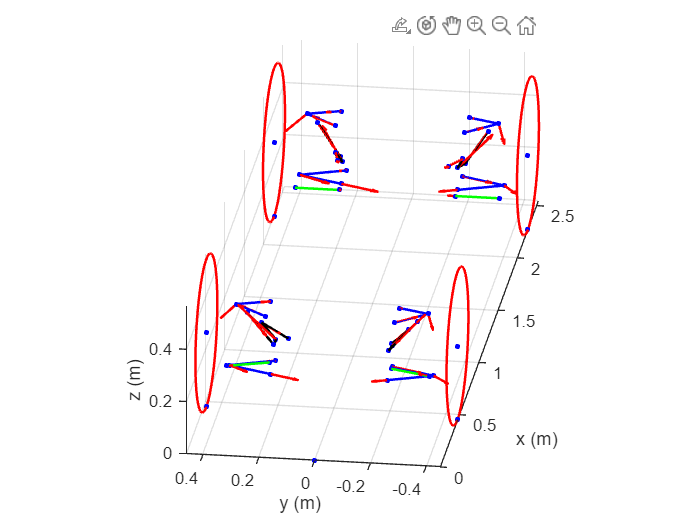

Corner_FL = calcForces(Corner_FL,f_FL_TP);
Corner_FR = calcForces(Corner_FR,f_FR_TP);
Corner_RL = calcForces(Corner_RL,f_RL_TP);
Corner_RR = calcForces(Corner_RR,f_RR_TP);

plotCornerForces(Corner_FL,figFull,forcevect_linewidth,forcevect_scalefactor);
plotCornerForces(Corner_FR,figFull,forcevect_linewidth,forcevect_scalefactor);
plotCornerForces(Corner_RL,figFull,forcevect_linewidth,forcevect_scalefactor);
plotCornerForces(Corner_RR,figFull,forcevect_linewidth,forcevect_scalefactor);